# Problem 1

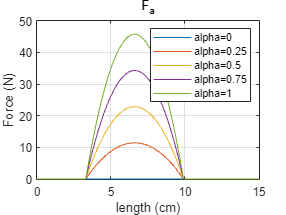

% Problem 2-a)
clear; clc; close all;

alpha = 0:0.25:1;
F_max = 45.7;
l_0 = 6.6;
% l_0 = 0.066;
K_sh = 3;
l = 0:0.1:15;


% there is no under Force(Voltage) in F_a
F_a = alpha' * F_max * ( 1 - 4 * ((l-l_0)./l_0).^2 );
F_a = max(F_a, 0);

% if l <= l_0, F_p = 0
% and in this code l = -y1 + l_o, so it means y1 > 0
if l < l_0
    F_p = 0;
else
    F_p = ( F_max/(exp(K_sh)-1) .* (exp( K_sh.*(l-l_0)./(0.5*l_0))-1) );
end

F_total = F_a + max(F_p,0);

% plot
figure(1)
plot(l,F_a)
title("F_a")
xlabel('length (cm)')
ylabel('Force (N)')
legend('alpha=0', 'alpha=0.25', 'alpha=0.5', 'alpha=0.75', 'alpha=1')
grid on

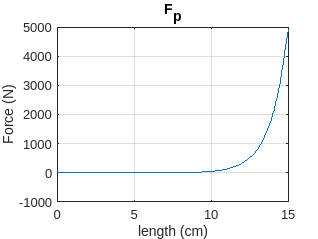

figure(2)
plot(l,F_p)
title("F_p")
xlabel('length (cm)')
ylabel('Force (N)')
grid on

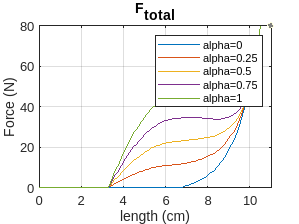

figure(3)
plot(l, F_total)
title("F_t_o_t_a_l")
xlabel('length (cm)')
ylabel('Force (N)')
legend('alpha=0', 'alpha=0.25', 'alpha=0.5', 'alpha=0.75', 'alpha=1')
xlim([0 11])
ylim([0 80])
grid on

1-(a) 그래프 표현 완료

% Problem 2 - b)
clear, clc, close all;

disp("solution of Problem 1 - b)")

solution of Problem 1 - b)


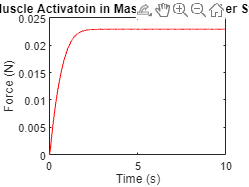


x_n = 0:0.01:10;
init_y = [0 0];
[t, y] = ode45(@hill_muscle_model_2ndODE, x_n, init_y);

% plot
figure(1)
plot(t, y(:, 1), 'r');
title('Muscle Activatoin in Mass-Spring-Damper System')
xlabel('Time (s)')
ylabel('Force (N)')
xlim([0 10])
ylim([0 0.025])

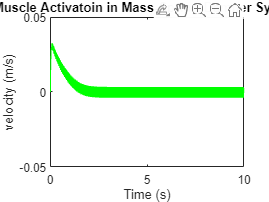


figure(2)
plot(t, y(:,2), 'g');
title('Muscle Activatoin in Mass-Spring-Damper System')
xlabel('Time (s)')
ylabel('velocity (m/s)')
xlim([0 10])
ylim([-0.050 0.05])

function dydt = hill_muscle_model_2ndODE(t, y)

% initial parameters
m=12; k=510; b=210; F_max=45.7; l_0=0.066; K_sh=3;
a1=0.8; a2=0.5; a3=0.43; a4=58;

% adjustable parameters
omega = 40;

y1 = y(1);
y2 = y(2);

factor_function = a1 + a2*atan(a3 + a4*(-y2));
alpha = (sin(omega*pi*t))^2;

% there is no under Force(Voltage) in F_a
F_a = alpha * F_max * (1-4 * (y1/l_0)^2);
F_a = max(F_a, 0);

% if l <= l_0, F_p = 0
% and in this code l = -y1 + l_o, so it means y1 > 0
if y1 > 0
    F_p = 0;
else
    F_p = (F_max/(exp(K_sh)-1)) * (exp( K_sh.*(-y1)/(0.5*l_0) )-1);
end

F_total = ( factor_function * (F_a + F_p) - b * y2 - k * y1 ) / m;

dxdt  = y2;
dxdt2 = F_total;

dydt = [dxdt; dxdt2];
end
